## **1 MATLAB On Ramping**

### 1.1 Completion Certificate:

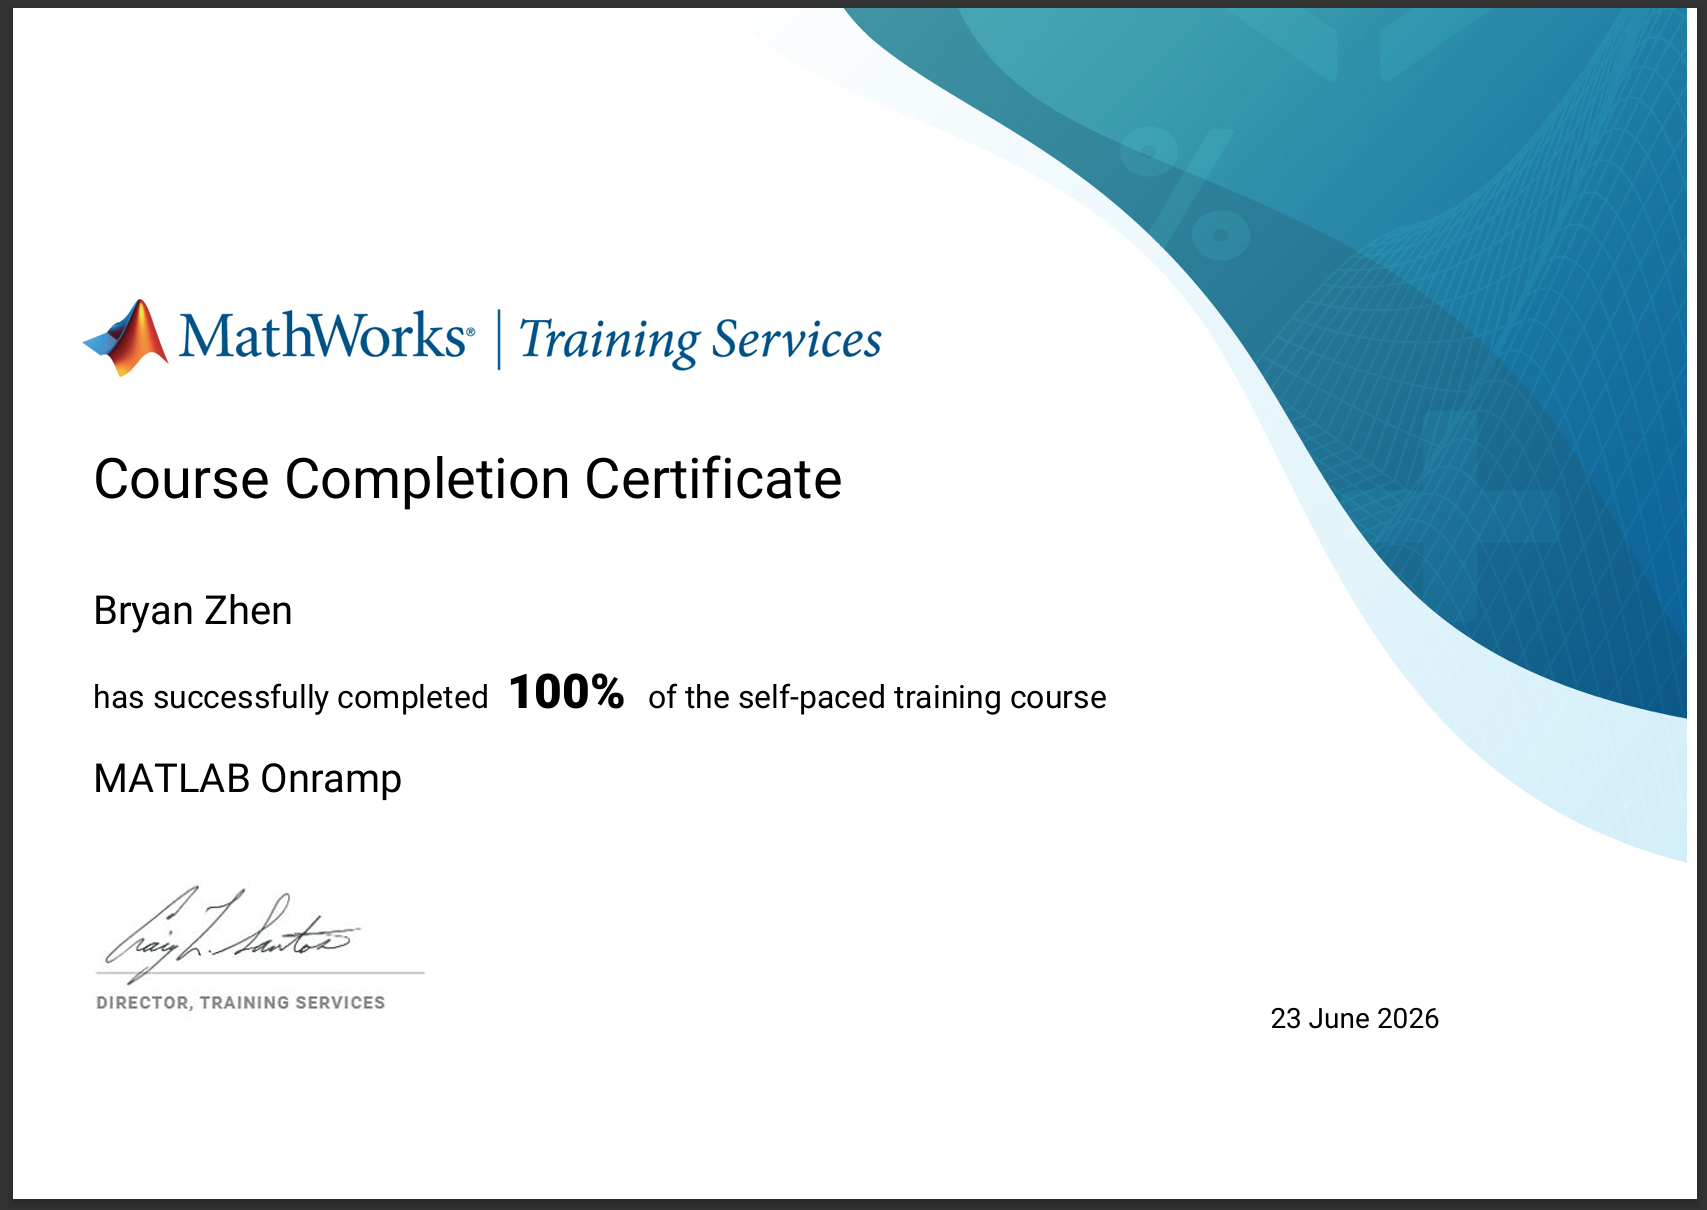

### 1.2 Summary

#### 1.2.1 Experience of Completing the Onramp

My experience completing this onramp consisted of me completing various set-out tasks on the Mathworks website. It provided me with brief, interactive lessons on how to do various things in a series of lessons. Generally, I found it to be a good overview that gave me a way to quickly get started on Matlab, though I would have preferred if they explained the programming sections in further depth, such as how to create while loops in Matlab.

#### 1.2.2 On ramping Summary

I was first introduced to basic arithmetic operators for addition, subtraction multiplication, and division. Afterwards, I learned how to assign values to a variable and how you can assign to a variable based on an operation. I was taught about the workspace layout and that matlab does not rerun previous commands in the command window. I was taught how to save my workspace using the save filename command. The commands section also taught me how to use built-in constants and set up functions.

The Matlab desktop and editor lesson taught me how to navigate Matlab’s interface itself and how to use the editor, interface, and run scripts. It also taught me how to identify marked errors in my code along with how to identify other underlines such as the orange warning underline.

The vectors and matrices lesson introduced me to how to enter in and manipulate vectors and matrices in matlab, where a space represents a different column while a semicolon represents a different row on the matrix. I was also taught how to make longer vectors without manually entering in the values. For example, the linspace command was taught along with how adding ‘ will transpose the vector. Basic function calls for matrices were also introduced.

The array indexing lesson taught me how to navigate around and extract and modify specific values from matrices using the row, column order in matlab along with using the built-in end variable to get the last value from a row or column.

The next few lessons were fairly short and taught me more basic functionalities.

Array calculations taught me how to do vector and matrix operations and function calls explained additional built-in functions I can call in Matlab. Documentation taught me how to access help and reference what specific functions and capabilities do in Matlab. The Plotting lessons taught me how to modify and overlay data in plots, set the axis values and titles, along with how to format my plots and modify their color and lines. The data Import Lessons taught me how to import spreadsheet data and modify it within matlab itself. Logical arrays taught me how to store values of relational operators within matrices. It also taught me how to use the AND(&) and OR(|) operators. These lessons were extended into how to use logical indexing to extract certain values from arrays with variables assigned logical operator values. The logical operators were fully explained with the conditional statements lesson along with how to use the if statement. The programming section expanded on how to use for loops.

In the final section, I used all of what I learned in order to process starlight data to see which stars were moving away and to also plot the data given.

## **2 Live Script Code Section**

### 2.1 Code and Commentary

We will first make the dropdown control for the sampling frequency by adjusting the sampling period, which will let us change the value of the sampling frequency between the 3 preset values of 0.3, 0.4, and 0.01 seconds.


%set value of sampling period using the dropdown control
T = 0.01;

We will then define t, the time variable, and the signal x, where x = sin(2*pi*t) varies over time. It is a discrete signal converted from a continuous one using the sampling frequency 1/T.


%time variable with sampling frequency T
t = 0:T:10; 

%make signal x
x = sin(2*pi*t);

We will then plot the signal on the y axis with time in seconds on the x-axis. A plot with a solid line and line width of 1 is used. The plot will automatically update its title and sampling frequency as the value of T is changed in the dropdown.

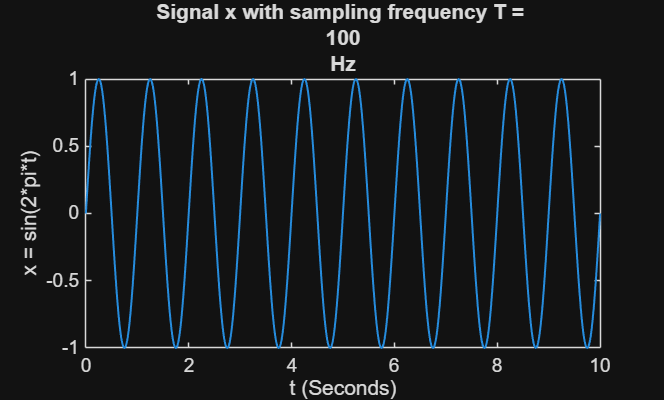


%make plot x vs t for 3 different T values
plot(t,x, "-", Linewidth = 1);
title(["Signal x with sampling frequency T = ", num2str(1/T), "Hz"]);
ylabel("x = sin(2*pi*t)");
xlabel("t (Seconds)");

%this plot will automatically update the plot as you adjust T.


### 2.2 Results Analysis

As seen by the plot when the code is run, as the sampling frequency increases, the discrete time signal begins to resemble a sin wave more and more. With a sampling period of 0.3 seconds or 0.4 seconds (which is a low sampling frequency), we see a jagged, distorted waveform, where the peaks are either flat for jagged for T = 0.3 and completely jagged for T = 0.4. T = 0.01 is smooth and practically resembles a sine wave completely.

since the signal is x = sin(2*pi*t), this is a 1 Hz sine wave, so the Nyquist frequency would be 2 Hz, as that is double the signal's maximum frequency.

As we choose a smaller sampling period, the inverse of the sampling period, the sampling frequency, will increase. When we choose a sampling period of 0.3 seconds or 0.4 seconds, this gives us a sampling frequency of 3.333Hz and 2.5Hz respectively, which is less than double the Nyquist frequency and therefore causes aliasing, distorting the signal on the plot. Although the frequencies here are not below the nyquist frequency, they are near the double amount of the Nyquist Frequency needed to accurately reconstruct the signal, causing the jagged plot.

In contrast, when the sampling period T is set to 0.01 seconds, the sampling frequency is 100Hz, which is well above double the nyquist frequency, giving us the ability to reconstruct the continuous waveform.